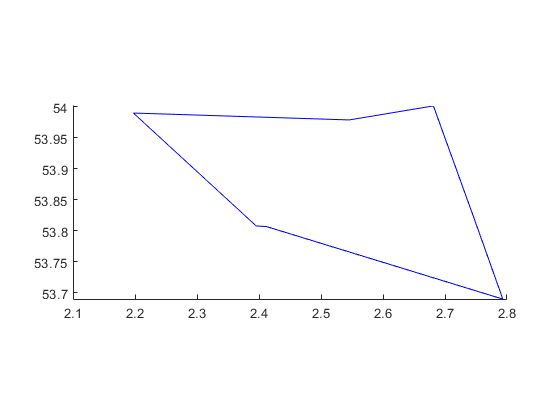

% reading hornsea shapefile
S = shaperead('horn3shape.shp');
% use: hornshape = S.Geometry to get coordinates of each corner
xv = S.X;
yv = S.Y;

% showing shape on the map
geoshow(yv,xv)



%Define x and y coordinates of 250 random query points. 
% Initialize the random-number generator to make the output of randn repeatable.
rng default
xq = rand(500,1)*0.9+2.1

xq =     2.8333
    2.9152
    2.2143
    2.9220
    2.6691
    2.1878
    2.3506
    2.5922
    2.9618
    2.9684


yq =  rand(500,1)*0.6+53.55

yq =    53.8993
   53.8744
   54.0720
   53.7089
   53.7408
   53.6215
   54.1139
   53.9373
   53.8377
   53.9336


%Determine whether each point lies inside or on the edge of the polygon area.
% Also determine whether any of the points lie on the edge of the polygon area.
[in,on] = inpolygon(xq,yq,xv,yv);

%Determine the number of points lying inside or on the edge of the polygon area.
numel(xq(in))

ans = 83


%Determine the number of points lying on the edge of the polygon area.
numel(xq(on))

ans = 0


%Since there are no points lying on the edge of the polygon area, 
% all 80 points identified by xq(in), yq(in) are strictly inside the polygon area.

%Determine the number of points lying outside the polygon area (not inside or on the edge).

numel(xq(~in))

ans = 417

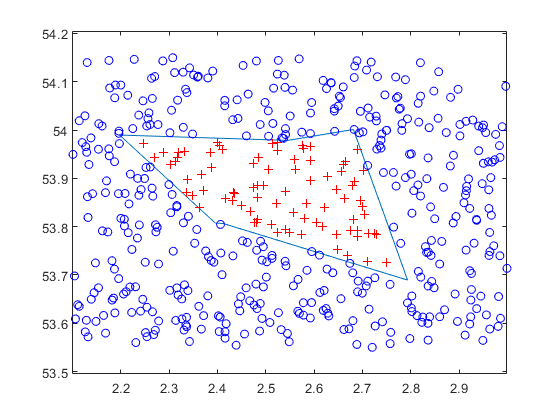

%Plot the polygon and the query points. Display the points inside the polygon with a red plus. Display the points outside the polygon with a blue circle.

figure

plot(xv,yv) % polygon
axis equal

hold on
plot(xq(in),yq(in),'r+') % points inside
plot(xq(~in),yq(~in),'bo') % points outside
hold off

testing distance func

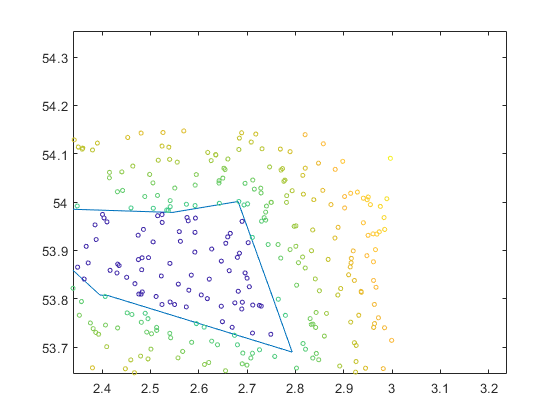


figure
plot(xv,yv) % polygon
axis equal
hold on

for i=1:length(xq)
    y=yq(i);
    x=xq(i);
    [d,x_poly,y_poly] = p_poly_dist(x, y, xv, yv); 
    if d <0 %if inside
        z(i)=0;
    else 
        z(i)=d*100+50;
    end
     
end

pointsize = 10;
scatter(xq, yq, pointsize, z);
hold off

function distance to polygon !

z(1)=2

z =     2.0000   67.6884   58.2875   63.0175         0   77.7472   62.9121         0   70.8395   74.7013   55.2924   75.3472   72.1075   50.3872   58.3857   65.7504   59.9956   65.1326   57.6256   69.8110         0   66.9728   59.3632   74.6213   50.2503   59.8776   63.9476   65.2131   55.3536   72.4358   53.9572   82.8710         0   62.7148   57.7768   59.5828         0         0   75.5407   63.8835   52.1457   64.9965   56.7416   52.7040   76.3613   52.4320   57.9837         0   54.0652   51.2234


cite as: 

Alejandro Weinstein (2022). Distance from a point to polygon (https://www.mathworks.com/matlabcentral/fileexchange/19398-distance-from-a-point-to-polygon), MATLAB Central File Exchange. Retrieved May 1, 2022.

%*******************************************************************************
% function:	p_poly_dist
% Description:	distance from point to polygon whose vertices are specified by the
%              vectors xv and yv
% Input:  
%    x - point's x coordinate
%    y - point's y coordinate
%    xv - vector of polygon vertices x coordinates
%    yv - vector of polygon vertices x coordinates
% Output: 
%    d - distance from point to polygon (defined as a minimal distance from 
%        point to any of polygon's ribs, positive if the point is outside the
%        polygon and negative otherwise)
%    x_poly: x coordinate of the point in the polygon closest to x,y
%    y_poly: y coordinate of the point in the polygon closest to x,y
%
% Routines: p_poly_dist.m
% Revision history:
%    03/31/2008 - return the point of the polygon closest to x,y
%               - added the test for the case where a polygon rib is 
%                 either horizontal or vertical. From Eric Schmitz.
%               - Changes by Alejandro Weinstein
%    7/9/2006  - case when all projections are outside of polygon ribs
%    23/5/2004 - created by Michael Yoshpe 
% Remarks:
%*******************************************************************************

function [d,x_poly,y_poly] = p_poly_dist(x, y, xv, yv) 
% If (xv,yv) is not closed, close it.
xv = xv(:);
yv = yv(:);
Nv = length(xv);
if ((xv(1) ~= xv(Nv)) || (yv(1) ~= yv(Nv)))
    xv = [xv ; xv(1)];
    yv = [yv ; yv(1)];
%     Nv = Nv + 1;
end
% linear parameters of segments that connect the vertices
% Ax + By + C = 0
A = -diff(yv);
B =  diff(xv);
C = yv(2:end).*xv(1:end-1) - xv(2:end).*yv(1:end-1);
% find the projection of point (x,y) on each rib
AB = 1./(A.^2 + B.^2);
vv = (A*x+B*y+C);
xp = x - (A.*AB).*vv;
yp = y - (B.*AB).*vv;
% Test for the case where a polygon rib is 
% either horizontal or vertical. From Eric Schmitz
id = find(diff(xv)==0);
xp(id)=xv(id);
clear id
id = find(diff(yv)==0);
yp(id)=yv(id);
% find all cases where projected point is inside the segment
idx_x = (((xp>=xv(1:end-1)) & (xp<=xv(2:end))) | ((xp>=xv(2:end)) & (xp<=xv(1:end-1))));
idx_y = (((yp>=yv(1:end-1)) & (yp<=yv(2:end))) | ((yp>=yv(2:end)) & (yp<=yv(1:end-1))));
idx = idx_x & idx_y;
% distance from point (x,y) to the vertices
dv = sqrt((xv(1:end-1)-x).^2 + (yv(1:end-1)-y).^2);
if(~any(idx)) % all projections are outside of polygon ribs
   [d,I] = min(dv);
   x_poly = xv(I);
   y_poly = yv(I);
else
   % distance from point (x,y) to the projection on ribs
   dp = sqrt((xp(idx)-x).^2 + (yp(idx)-y).^2);
   [min_dv,I1] = min(dv);
   [min_dp,I2] = min(dp);
   [d,I] = min([min_dv min_dp]);
   if I==1, %the closest point is one of the vertices
       x_poly = xv(I1);
       y_poly = yv(I1);
   elseif I==2, %the closest point is one of the projections
       idxs = find(idx);
       x_poly = xp(idxs(I2));
       y_poly = yp(idxs(I2));
   end
end
if(inpolygon(x, y, xv, yv)) 
   d = -d;
end

end

calculating cost for being outside boundary : inside 